%reading the audio file
[a fs]=audioread("C:\Users\pooja\Desktop\Cryptography\sig100.wav")

a =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


fs = 360


%extracting the first 10 seconds of the audio file
%a_cut = a((fs * (10- 1)) + 1 : fs * ( 20- 1), :)



%padding zeros to make a square matrix
a_cut=a

a_cut =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156



%making the 2 channel file a single channel file
a_cut_mono=reshape(a_cut,[],1)

a_cut_mono =    -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0283
   -0.0234
   -0.0264



%finding the factors of the no of rows
n=(size(a_cut_mono))

n =      1300000           1


n=n(1)

n = 1300000

factors=factorList(n);
size(factors)

ans =      1    71





%creating ordered pairs of possible combinations
pairs=combinations(n,factors)

count = 1

pairs =            2      650000
           4      325000
           5      260000
           8      162500
          10      130000
          13      100000
          16       81250
          20       65000
          25       52000
          26       50000



optimal_pair =[pairs(1,:)];
minzero=0;
pairs

pairs =            2      650000
           4      325000
           5      260000
           8      162500
          10      130000
          13      100000
          16       81250
          20       65000
          25       52000
          26       50000


for i = 1:size(pairs,1)/2;
    temppair=[pairs(i,:)];
    temppair(1);
    temppair(2);
    zeroes = optimize(temppair(1), temppair(2));
    zeroes;
    if minzero == 0
        minzero = zeroes;
    else
       if zeroes < minzero
           minzero = zeroes;
           optimal_pair = temppair;
        end
    end
end
minzero

minzero = 262500

temp=optimal_pair(1)

temp = 1040

optimal_pair(1)=optimal_pair(2)

optimal_pair =         1250        1250


optimal_pair(2)=temp

optimal_pair =         1250        1040



a_reshaped=reshape(a_cut,optimal_pair(1),optimal_pair(2))

a_reshaped =    -0.0283   -0.0791   -0.0947   -0.0586   -0.0449   -0.0771   -0.0576   -0.0820    0.0850   -0.0850   -0.0791   -0.0732   -0.1074   -0.0762   -0.0527   -0.0684   -0.0674   -0.0498   -0.0635   -0.0459   -0.0811   -0.0596   -0.0518   -0.0820   -0.0576   -0.0566   -0.0742   -0.0732   -0.0508   -0.0400    0.1670   -0.0928   -0.0723   -0.0713   -0.0879   -0.0596   -0.0664   -0.0889   -0.0684   -0.0801   -0.0752   -0.0684   -0.0605   -0.0674   -0.0439   -0.0674   -0.0605   -0.0557   -0.0732   -0.0615
   -0.0283   -0.0791   -0.0967   -0.0605   -0.0469   -0.0762   -0.0576   -0.0830    0.0127   -0.0840   -0.0791   -0.0742   -0.1162   -0.0791   -0.0547   -0.0674   -0.0693   -0.0479   -0.0615   -0.0176   -0.0830   -0.0586   -0.0518   -0.0840   -0.0557   -0.0537   -0.0732   -0.0732   -0.0488   -0.0400    0.1328   -0.0928   -0.0713   -0.0752   -0.0859   -0.0576   -0.0654   -0.0918   -0.0654   -0.0898   -0.0781   -0.0674   -0.0293   -0.0693   -0.0410   -0.0664   -0.0596   -0.0576   -0.

size(a_reshaped)

ans =         1250        1040


if optimal_pair(1)>optimal_pair(2)
   
    sq_wave = [a_reshaped, zeros(optimal_pair(1),optimal_pair(1)-optimal_pair(2))]
    
else
    a_reshaped=(a_reshaped)'
    size(a_reshaped)
    sq_wave = [a_reshaped, zeros(optimal_pair(2),optimal_pair(2)-optimal_pair(1))]
    
end

sq_wave =    -0.0283   -0.0791   -0.0947   -0.0586   -0.0449   -0.0771   -0.0576   -0.0820    0.0850   -0.0850   -0.0791   -0.0732   -0.1074   -0.0762   -0.0527   -0.0684   -0.0674   -0.0498   -0.0635   -0.0459   -0.0811   -0.0596   -0.0518   -0.0820   -0.0576   -0.0566   -0.0742   -0.0732   -0.0508   -0.0400    0.1670   -0.0928   -0.0723   -0.0713   -0.0879   -0.0596   -0.0664   -0.0889   -0.0684   -0.0801   -0.0752   -0.0684   -0.0605   -0.0674   -0.0439   -0.0674   -0.0605   -0.0557   -0.0732   -0.0615
   -0.0283   -0.0791   -0.0967   -0.0605   -0.0469   -0.0762   -0.0576   -0.0830    0.0127   -0.0840   -0.0791   -0.0742   -0.1162   -0.0791   -0.0547   -0.0674   -0.0693   -0.0479   -0.0615   -0.0176   -0.0830   -0.0586   -0.0518   -0.0840   -0.0557   -0.0537   -0.0732   -0.0732   -0.0488   -0.0400    0.1328   -0.0928   -0.0713   -0.0752   -0.0859   -0.0576   -0.0654   -0.0918   -0.0654   -0.0898   -0.0781   -0.0674   -0.0293   -0.0693   -0.0410   -0.0664   -0.0596   -0.0576   -0.069



%generating a random key
key=rand(size(sq_wave))

key =     0.4824    0.5107    0.3832    0.4052    0.8379    0.8184    0.3755    0.4822    0.7089    0.8157    0.0994    0.8253    0.3607    0.1492    0.2623    0.5895    0.7279    0.2576    0.8357    0.7873    0.7152    0.2830    0.9718    0.0775    0.4074    0.8218    0.6459    0.4018    0.1857    0.6565    0.4115    0.5420    0.3053    0.5287    0.0604    0.8275    0.1371    0.4641    0.0556    0.3115    0.8923    0.3474    0.0963    0.4438    0.3498    0.3177    0.9924    0.0870    0.8960    0.3271
    0.2747    0.9345    0.6426    0.4562    0.6163    0.4805    0.1041    0.1939    0.6634    0.7348    0.4721    0.6991    0.4701    0.2192    0.4612    0.5125    0.2022    0.0698    0.6498    0.4597    0.9209    0.0092    0.1268    0.9814    0.7569    0.4889    0.2743    0.1654    0.6342    0.5948    0.3875    0.8827    0.4176    0.5132    0.4036    0.1301    0.4502    0.6886    0.7355    0.8525    0.5620    0.9025    0.2598    0.9808    0.2051    0.3673    0.7312    0.1791    0.9336   


%encryption
enc=sq_wave*key

enc =   -25.2147  -24.3730  -25.0139  -23.3466  -24.4397  -25.2749  -25.5508  -25.1439  -24.2446  -25.2382  -23.9489  -23.5943  -24.2175  -25.6400  -23.4265  -24.0975  -24.7689  -24.1760  -25.3206  -24.4509  -25.4065  -24.2669  -24.4596  -24.8449  -24.1010  -25.2403  -24.9932  -24.6376  -24.8461  -24.5136  -24.3087  -24.5340  -23.6542  -24.9803  -24.2761  -25.2851  -24.9102  -25.0006  -25.2933  -24.9298  -23.9001  -24.5601  -24.3866  -24.1618  -23.4481  -25.2883  -25.3512  -25.1162  -24.7216  -25.2712
  -25.2066  -24.2008  -24.9124  -23.4022  -24.4132  -25.1646  -25.5075  -25.1422  -24.3017  -25.2696  -23.8898  -23.7224  -24.2556  -25.3665  -23.5520  -24.0955  -24.7863  -24.0828  -25.4104  -24.3549  -25.4828  -24.2664  -24.5679  -24.7426  -23.8964  -25.0362  -24.9708  -24.5195  -25.0227  -24.5443  -24.3546  -24.5740  -23.7800  -24.9404  -24.2593  -25.3337  -24.9988  -24.8707  -25.2410  -24.8744  -23.9429  -24.4609  -24.4370  -24.2055  -23.4792  -25.1279  -25.2657  -25.0812  -24.8029  -

enc_col=enc(:,1)

enc_col =   -25.2147
  -25.2066
  -25.1586
  -24.9874
  -24.7548
  -24.5835
  -24.4232
  -24.3307
  -24.1549
  -23.9855



%decryption
dec=enc*inv(key)

dec =    -0.0283   -0.0791   -0.0947   -0.0586   -0.0449   -0.0771   -0.0576   -0.0820    0.0850   -0.0850   -0.0791   -0.0732   -0.1074   -0.0762   -0.0527   -0.0684   -0.0674   -0.0498   -0.0635   -0.0459   -0.0811   -0.0596   -0.0518   -0.0820   -0.0576   -0.0566   -0.0742   -0.0732   -0.0508   -0.0400    0.1670   -0.0928   -0.0723   -0.0713   -0.0879   -0.0596   -0.0664   -0.0889   -0.0684   -0.0801   -0.0752   -0.0684   -0.0605   -0.0674   -0.0439   -0.0674   -0.0605   -0.0557   -0.0732   -0.0615
   -0.0283   -0.0791   -0.0967   -0.0605   -0.0469   -0.0762   -0.0576   -0.0830    0.0127   -0.0840   -0.0791   -0.0742   -0.1162   -0.0791   -0.0547   -0.0674   -0.0693   -0.0479   -0.0615   -0.0176   -0.0830   -0.0586   -0.0518   -0.0840   -0.0557   -0.0537   -0.0732   -0.0732   -0.0488   -0.0400    0.1328   -0.0928   -0.0713   -0.0752   -0.0859   -0.0576   -0.0654   -0.0918   -0.0654   -0.0898   -0.0781   -0.0674   -0.0293   -0.0693   -0.0410   -0.0664   -0.0596   -0.0576   -0.0693   


%dec=dec(:,1)


%converting it back into a 2 channel file

orig=reshape(dec,[],2);

%comparison of original file and decrypted file
a_cut

a_cut =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


orig

orig =    -0.0283    0.0254
   -0.0283    0.0273
   -0.0283    0.0264
   -0.0283    0.0244
   -0.0283    0.0244
   -0.0283    0.0244
   -0.0283    0.0273
   -0.0283    0.0303
   -0.0234    0.0283
   -0.0264    0.0273




%plotting the original, encrypted and decrypted waves

%original 2 channel waveform

t_og=(0:length(a_cut)-1)/fs

t_og = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


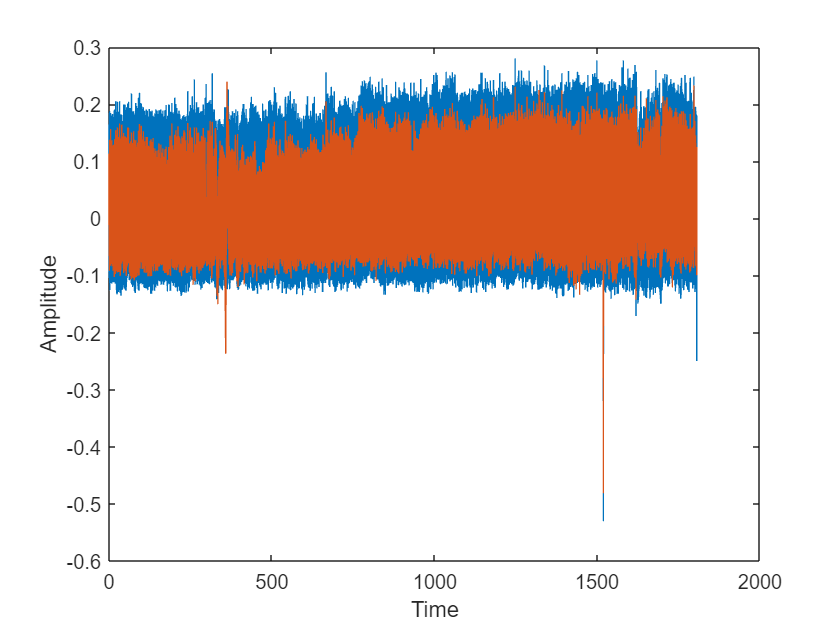

plot(t_og,a_cut)
xlabel("Time")
ylabel("Amplitude")


%encrypted mono channel waveform
t_enc=(0:length(enc_col)-1)/fs

t_enc =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


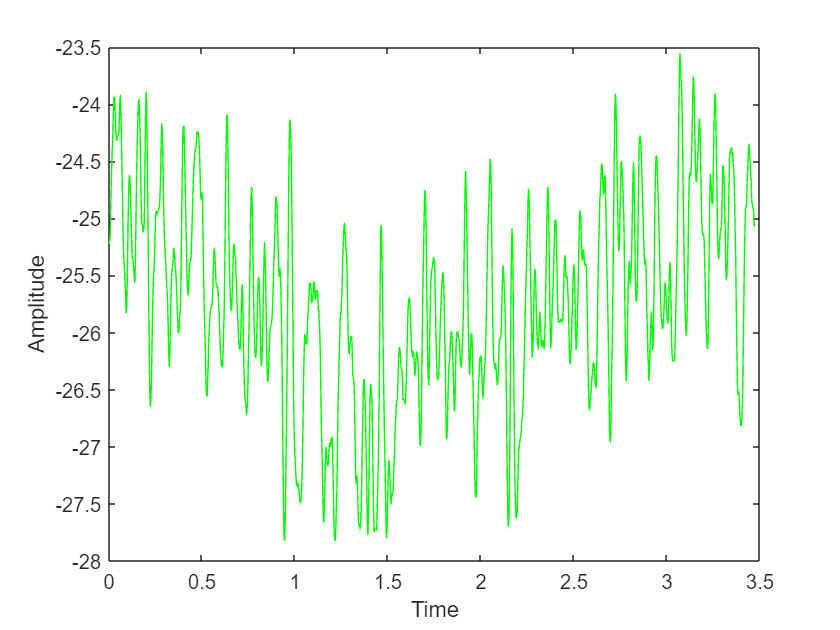

plot(t_enc,enc_col,'g')
xlabel("Time")
ylabel("Amplitude")


%decrypted 2 channel waveform
t_dec=(0:length(orig)-1)/fs

t_dec = 1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


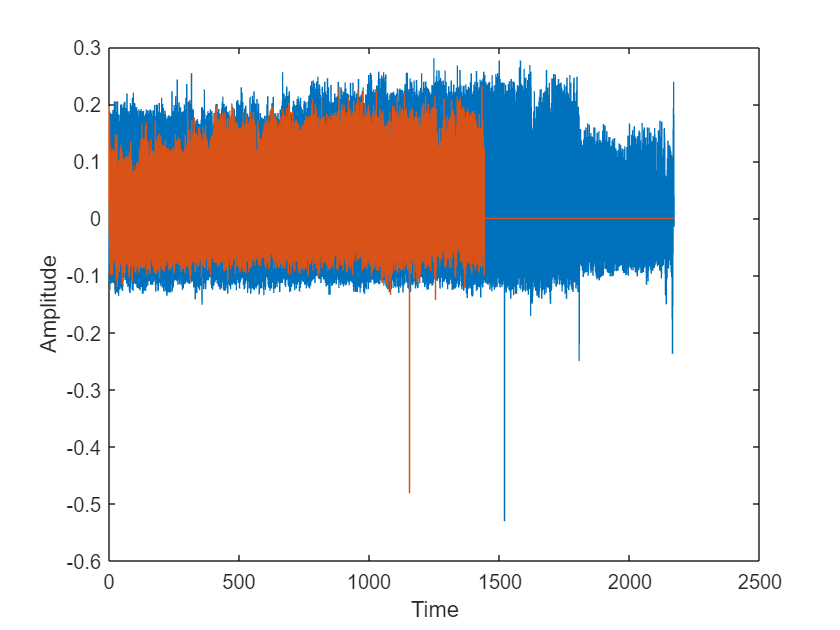

plot(t_dec,orig)
xlabel("Time")
ylabel("Amplitude")